**Find 2nd Order Transient Characteristics**

% clear
% G = tf(9, [1 2 9]); % define transfer function from coefficients
% damp(G) % damping is zeta and freq is omega_n

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+00 + 2.83e+00i     3.33e-01       3.00e+00         1.00e+00    
 -1.00e+00 - 2.83e+00i     3.33e-01       3.00e+00         1.00e+00    


% 
% % verify hand calculations
% stepinfo(G)

ans = struct with fields:
         RiseTime: 0.4568
    TransientTime: 3.7005
     SettlingTime: 3.7005
      SettlingMin: 0.8916
      SettlingMax: 1.3293
        Overshoot: 32.9277
       Undershoot: 0
             Peak: 1.3293
         PeakTime: 1.1052



% solve for %OS given zeta
OS = 24.9;   % SPECIFY percent overshoot
zeta = -log(OS/100) / sqrt(pi^2 + log(OS/100)^2)

zeta = 0.4047



% find desired pole location given %OS and Ts targets
Ts_target = 1.48/2; %%% SPECIFY
sigma = 4 / Ts_target        % real part

sigma = 5.4054

wd    = sigma * tan(acos(zeta))  % imaginary part

wd = 12.2143

wd2 = sigma/zeta*sqrt(1-zeta^2) % double check

wd2 = 12.2143

desired_pole = -sigma + 1j*wd

desired_pole = -5.4054 +12.2143i

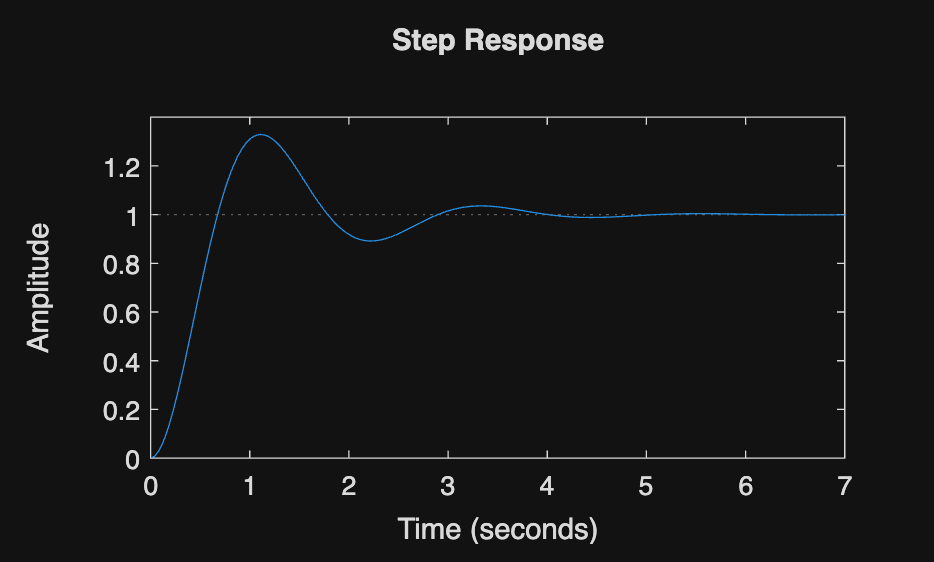


%Plot step response with spec lines overlaid
step(G)

% In the figure window: right-click → Characteristics
% → Peak Response, Settling Time, Rise Time

% Or use sgrid on a pzmap to see constant-%OS lines:
pzmap(G)
sgrid
% Lines radiating from origin = constant ζ (constant %OS)
% Semicircles = constant ωₙ


%Plot full system vs 2nd order approximation — visual confirmation
% Build 2nd order approximation from dominant poles
wn2  = sqrt(sigma^2 + wd^2);
zeta2 = sigma / wn2;
T_approx = tf(wn2^2, [1, 2*zeta2*wn2, wn2^2]);
% show the poles of this transfer function
p_approx = pole(T_approx)

p_approx =   -5.4054 +12.2143i
  -5.4054 -12.2143i


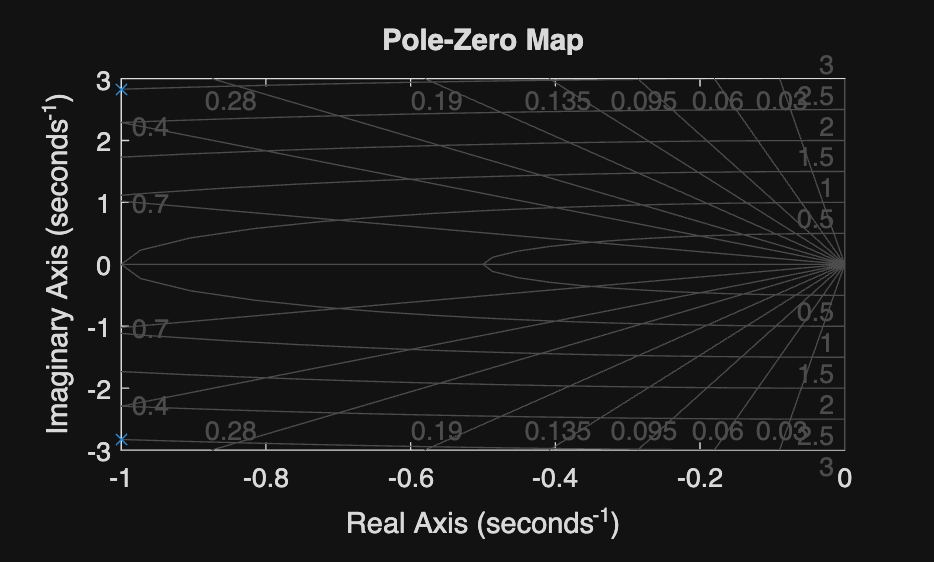

pzmap(T_approx)

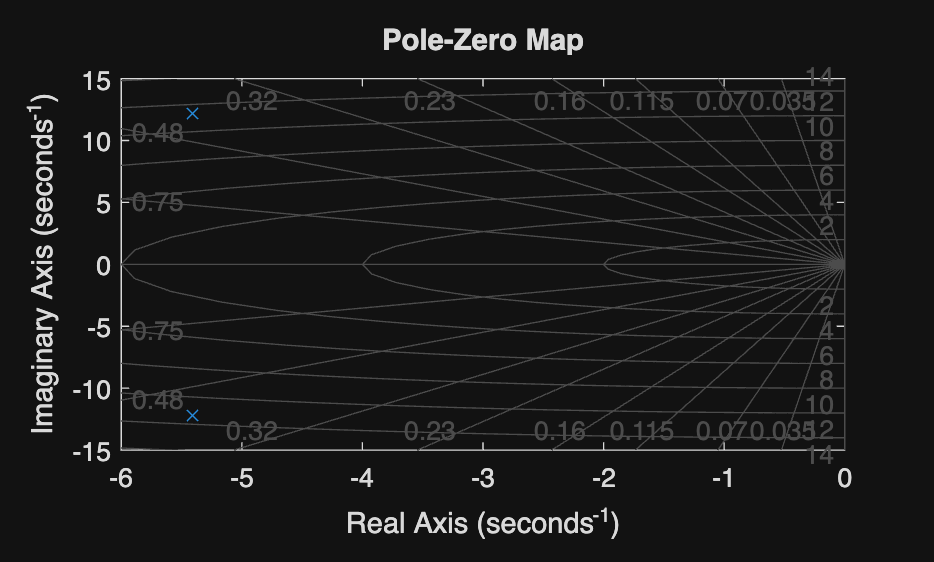

sgrid


% Plot and automatically display peak time and settling time for the approx
h = stepplot(T_approx);
info = stepinfo(T_approx)

info = struct with fields:
         RiseTime: 0.1103
    TransientTime: 0.6295
     SettlingTime: 0.6295
      SettlingMin: 0.9381
      SettlingMax: 1.2489
        Overshoot: 24.8941
       Undershoot: 0
             Peak: 1.2489
         PeakTime: 0.2556


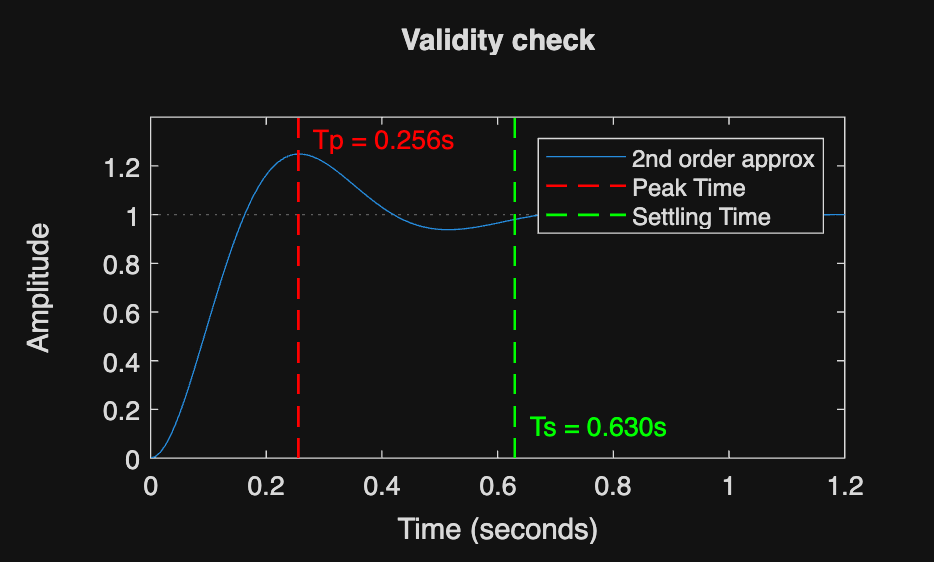

% Add annotations for Peak Time and Settling Time
pt = info.PeakTime;
st = info.SettlingTime;
ypt = 1 + info.Overshoot/100 * 1; % approximate peak output (step magnitude = 1)
yl = ylim;
hold on
plot([pt pt], yl, 'r--', 'LineWidth', 1);
plot([st st], yl, 'g--', 'LineWidth', 1);
text(pt, min(ypt, yl(2)), sprintf('  Tp = %.3fs', pt), 'Color','r','VerticalAlignment','bottom');
text(st, yl(1) + 0.05*(yl(2)-yl(1)), sprintf('  Ts = %.3fs', st), 'Color','g','VerticalAlignment','bottom');
hold off
legend('2nd order approx','Peak Time','Settling Time')
title('Validity check')

**Given closed loop poles, verify **

ex. Closed-loop poles at `s = −2.7 ± j6.1, −2.9, −14.7` with K=430, zero at s=−3. Find the damping ratio and predicted %OS.

clear
syms s
% G(s) from the question. 
% use conv to multiply coefficient vectors (1st order polynomials)

% G(s) = (s+3)/[(s+2)(s+5)(s+6)(s+10)]
z1 = -3

z1 = -3

p1 = -2

p1 = -2

p2 = -5

p2 = -5

p3 = -6

p3 = -6

p4 = -10

p4 = -10

G_check = (s-z1)/(expand((s-p1)*(s-p2)*(s-p3)*(s-p4)))

Unrecognized function or variable 's'.


G = tf([1 3], conv([1 2], conv([1 5], conv([1 6],[1 10]))))


% form closed-loop TF from open-loop product K*G
K = 430;
T = feedback(K*G, 1);   % closed-loop TF

step(T) % step response = output when input is a step
% In the figure window: right-click → Characteristics
% → Peak Response, Settling Time, Rise Time

% confirm pole locations
pole(T)

%Get ζ and ωₙ directly 
damp(T)

% Compute all specs for verification
% Read from dominant poles
sigma = 2.7037;
wd    = 6.1011;
wn    = sqrt(sigma^2 + wd^2);
zeta  = sigma / wn;

% Hand formulas
OS_hand = exp(-zeta*pi / sqrt(1-zeta^2)) * 100 % assumes 2nd order
Ts_hand = 4 / sigma
Tp_hand = pi / wd

% MATLAB verification
info = stepinfo(T);
OS_matlab = info.Overshoot % simulates full 4th order system including non-dominant poles and imperfect pole-zero cancellation
Ts_matlab = info.SettlingTime
Tp_matlab = info.PeakTime


%Check the 5× rule and pole-zero cancellation
p = pole(T);
z = zero(T);
sigma_dom = abs(real(p(1)));   % 2.70

% 5x check for each non-dominant pole
for i = 3:length(p)
    ratio = abs(real(p(i))) / sigma_dom;
    fprintf('s=%.2f:  ratio=%.1fx  ', real(p(i)), ratio);
    if ratio >= 5, fprintf('negligible\n');
    else,          fprintf('check for zero cancellation\n'); end
end

% Pole-zero proximity check
fprintf('\nZeros: '); disp(z')
fprintf('Close pairs (within 0.3):\n')
for i=1:length(z)
  for j=1:length(p)
    if abs(z(i)-p(j)) < 0.3
      fprintf('  zero %.3f  ≈  pole %.3f\n', z(i), real(p(j)));
    end
  end
end


%Plot full system vs 2nd order approximation — visual confirmation
% Build 2nd order approximation from dominant poles
wn2  = sqrt(sigma^2 + wd^2);
zeta2 = sigma / wn2;
T_approx = tf(wn2^2, [1, 2*zeta2*wn2, wn2^2]);

step(T, T_approx)
legend('Full system (K=430)', '2nd order approx')
title('2018 Q2b — validity check')

**from slides**

a = 5;

G = zpk([], [0 -a], 1);

pos = 10;

zeta = -log(pos/100) / sqrt(pi^2 + (log(pos/100))^2);

K = a^2 / (4 * zeta^2);

Wn = sqrt(K);

rlocus(G)
sgrid(zeta, Wn);
pause;

G_cl = K * G / (1 + K * G);

step(G_cl)

[y, t] = step(G_cl);

max(y)